Author: Graeme Dockrill, VDX sub-team member 2022

Modified by: Liam Foster, mechanical lead 2023

Function description: 

This script reads suspension hardpoints from the "Brightside V2 Suspension Geometry Design" Google Sheet, plots the suspension system in 3D and calculates the forces in each member

% Clear the console and all variables
clear
clc

% ----------------Setup----------------------------------------------------

% Constants
hardpointsize = 10;
LineWidth = 1.5;
unitvect_scalefactor = 0.05;
unitvect_linewidth = 1.5;
forcevect_scalefactor = 0.00005;
forcevect_linewidth = 1.5;

% x,y,z for clearer equations
x = 1;
y = 2;
z = 3;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);
coordinates = [data.X(1:32) data.Y(1:32) data.Z(1:32)];
forces = [data.X(33:36) data.Y(33:36) data.Z(33:36)];

% Converting values read from excel to 3D points
O = coordinates(1,x:z);
MC = coordinates(2,x:z);

% Front hardpoints
F_LCA_IR = coordinates(3,x:z);
F_LCA_IF= coordinates(4,x:z);
F_LCA_O = coordinates(5,x:z);
F_UCA_IR = coordinates(6,x:z);
F_UCA_IF = coordinates(7,x:z);
F_UCA_O = coordinates(8,x:z);
F_PR_O = coordinates(9,x:z);
F_PR_I = coordinates(10,x:z);
F_RP = coordinates(11,x:z);
F_RS = coordinates(12,x:z);
F_SC = coordinates(13,x:z);
F_TR_O = coordinates(14,x:z);
F_TR_I = coordinates(15,x:z);
F_WC = coordinates(16,x:z);
F_TP = coordinates(17,x:z);

% Rear hardpoints
R_LCA_IR = coordinates(18,x:z);
R_LCA_IF = coordinates(19,x:z);
R_LCA_O = coordinates(20,x:z);
R_UCA_IR = coordinates(21,x:z);
R_UCA_IF = coordinates(22,x:z);
R_UCA_O = coordinates(23,x:z);
R_PR_O = coordinates(24,x:z);
R_PR_I = coordinates(25,x:z);
R_RP = coordinates(26,x:z);
R_RS = coordinates(27,x:z);
R_SC = coordinates(28,x:z);
R_TR_O = coordinates(29,x:z);
R_TR_I = coordinates(30,x:z);
R_WC = coordinates(31,x:z);
R_TP = coordinates(32,x:z);

% Creating matrices for each part for plotting purposes
F_LCA = [F_LCA_IF; F_LCA_O; F_LCA_IR];  % Front lower control arm
F_UCA = [F_UCA_IF; F_UCA_O; F_UCA_IR];  % Front upper control arm
F_PR = [F_PR_O; F_PR_I];                % Front push/pull rod
F_R = [F_PR_I; F_RP; F_RS;];            % Front rocker
F_S = [F_RS; F_SC];                     % Front shock
F_TR = [F_TR_O; F_TR_I];                % Front steering tie-rod

R_LCA = [R_LCA_IF; R_LCA_O; R_LCA_IR];  % Rear lower control arm
R_UCA = [R_UCA_IF; R_UCA_O; R_UCA_IR];  % Rear upper control arm
R_PR = [R_PR_O; R_PR_I];                % Rear push/pull rod
R_R = [R_PR_I; R_RP; R_RS];             % Rear rocker
R_S = [R_RS; R_SC];                     % Rear shock
R_TR = [R_TR_O; R_TR_I];                % Rear steering tie-rod

% Converting input forces from excel to 3D vectors
FO_F = forces(1,x:z);
FI_F = forces(2,x:z);
RO_F = forces(3,x:z);
RI_F = forces(4,x:z);

% Setting labels for each point in coordinates
% labels = {'Origin', 'I_LCA_R', 'O_LCA', 'I_LCA_F', 'I_UCA_R', 'O_UCA', 'I_UCA_F', 'O_PR', 'I_PR', 'RP', 'RS', 'SC', 'O_TR', 'I_TR', 'WC', 'TP'};


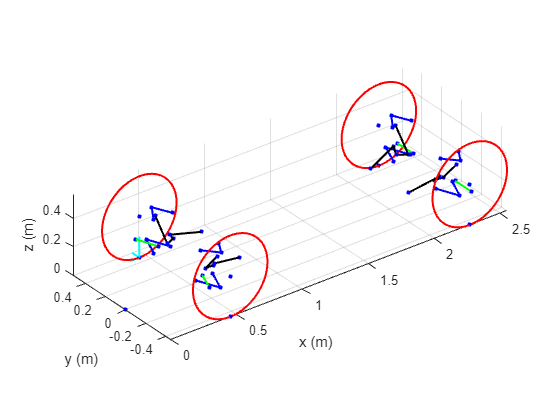

% ----------------Plotting-------------------------------------------------


% Plotting all points for control arms
scatter3(coordinates(:,x), coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');
hold on
scatter3(coordinates(:,x), -coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');

% Plotting x,y,z components of contact patch force
quiver3(F_TP(x), F_TP(y), F_TP(z), FO_F(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, FO_F(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, 0, FO_F(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);


% Drawing lines for front right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for front left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), -F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), -F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), -F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), -F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), -F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), -F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), -R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), -R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), -R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), -R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), -R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), -R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Labelling axes and setting their aspect ratio
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
axis equal

% Labelling each point in the plot
% text(coordinates(2:17,x), coordinates(2:17,y), coordinates(2:17,z), labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom');
% Labelling Moment Center separately
% text(coordinates(x,14), coordinates(y,14), coordinates(z,14), 'MomCent', 'HorizontalAlignment','center', 'VerticalAlignment','top');


% Drawing tires
t = linspace(0,2*pi);
F_tx = F_WC(z)*sin(t) + F_WC(x);
F_ty = 0*t + F_WC(y);
F_tz = F_WC(z)*cos(t) + F_WC(z);
F_wheel = [F_tx;F_ty;F_tz];
plot3(F_wheel(1,:),F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(F_wheel(1,:),-F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
R_tx = R_WC(z)*sin(t) + R_WC(x);
R_ty = 0*t + R_WC(y);
R_tz = R_WC(z)*cos(t) + R_WC(z);
R_wheel = [R_tx;R_ty;R_tz];
plot3(R_wheel(1,:),R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(R_wheel(1,:),-R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)

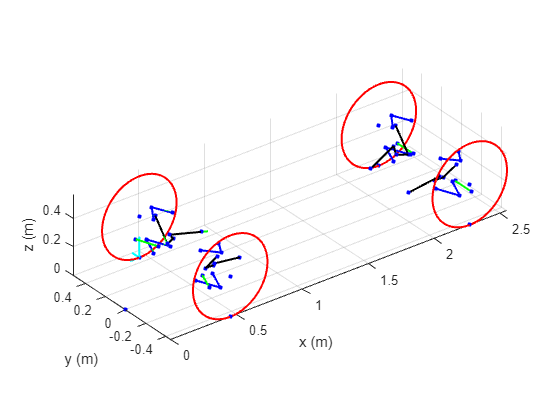

% ----------------Calculating unit vector of members-----------------------


% getting unit vectors along each member
% (inboard - outboard coordinates) / magnitude
uLCA_F = (F_LCA_O-F_LCA_IF)/(norm(F_LCA_O-F_LCA_IF)); % the same as "n" shown in the matrix A
uLCA_R = (F_LCA_O-F_LCA_IR)/(norm(F_LCA_O-F_LCA_IR));
uUCA_F = (F_UCA_O-F_UCA_IF)/(norm(F_UCA_O-F_UCA_IF));
uUCA_R = (F_UCA_O-F_UCA_IR)/(norm(F_UCA_O-F_UCA_IR));
uPR = (F_PR_O-F_PR_I)/(norm(F_PR_O-F_PR_I));
uSC = (F_SC-F_RS)/(norm(F_SC-F_RS));
uTR = (F_TR_O-F_TR_I)/(norm(F_TR_O-F_TR_I));

% plotting unit vector for bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), uLCA_F(x), uLCA_F(y), uLCA_F(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), uLCA_R(x), uLCA_R(y), uLCA_R(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), uUCA_F(x), uUCA_F(y), uUCA_F(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), uUCA_R(x), uUCA_R(y), uUCA_R(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for push/pull rod
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), uPR(x), uPR(y), uPR(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for shock
quiver3(F_SC(x), F_SC(y), F_SC(z), uSC(x), uSC(y), uSC(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), uTR(x), uTR(y), uTR(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% ----------------Calculating Moments--------------------------------------


% getting moment arm from MomCent for each member
rTR = F_TR_I-MC;
rPR = F_PR_I-MC;
rLCA_R = F_LCA_IR-MC;
rLCA_F = F_LCA_IF-MC;
rUCA_R = F_UCA_IR-MC;
rUCA_F = F_UCA_IF-MC;
rTP = F_TP-MC;

% Mx = rxF

% Moments around MomCent from input forces
M_Fx = cross(rTP,[FO_F(x); 0; 0]);
M_Fy = cross(rTP,[0; FO_F(y); 0]);
M_Fz = cross(rTP,[0; 0; FO_F(z)]);


% Moments for each member about the origin
M_UCA_F = cross(rUCA_F, uUCA_F);
M_UCA_R = cross(rUCA_R, uUCA_R);
M_LCA_F = cross(rLCA_F, uLCA_F);
M_LCA_R = cross(rLCA_R, uLCA_R);
M_PR = cross(rPR, uPR);
M_TR = cross(rTR, uTR);


% ----------------Setting up Matrix to solve-------------------------------


% 6x6 matrix from sum of forces and sum of moments about MomCent
A = [uUCA_F(x),    uUCA_R(x),     uLCA_F(x),     uLCA_R(x),     uPR(x),     uTR(x);
    uUCA_F(y),    uUCA_R(y),     uLCA_F(y),     uLCA_R(y),     uPR(y),     uTR(y);
    uUCA_F(z),    uUCA_R(z),     uLCA_F(z),     uLCA_R(z),     uPR(z),     uTR(z);
    M_UCA_F(x),   M_UCA_R(x),    M_LCA_F(x),    M_LCA_R(x),    M_PR(x),    M_TR(x);
    M_UCA_F(y),   M_UCA_R(y),    M_LCA_F(y),    M_LCA_R(y),    M_PR(y),    M_TR(y);
    M_UCA_F(z),   M_UCA_R(z),    M_LCA_F(z),    M_LCA_R(z),    M_PR(z),    M_TR(z)];


% Make input matrix B=[-F(x); -F(y); -F(z); -M(x); -M(y); -M(z)]
B = [-FO_F(x); -FO_F(y); -FO_F(z); -(M_Fx(x)+M_Fy(x)+M_Fz(x)); -(M_Fx(y)+M_Fy(y)+M_Fz(y)); -(M_Fx(z)+M_Fy(z)+M_Fz(z))];


% ----------------Solve for Forces in Members------------------------------


F_Mat = A\B

F_Mat = 1.0e+03 *

    1.9014
    4.0042
    1.3540
   -7.2498
   -4.4096
    2.0707


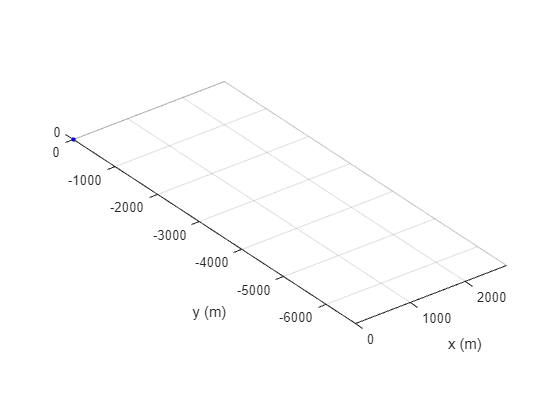


% Formatting of X: X = [F_UCA_F, F_UCA_R, F_LCA_F, F_LCA_R, F_PR, F_TR]

% Each member force as a 3x1 vector
F_UCA_F = F_Mat(1)*uUCA_F;
F_UCA_R = F_Mat(2)*uUCA_R;
F_LCA_F = F_Mat(3)*uLCA_F;
F_LCA_IR = F_Mat(4)*uLCA_R;
F_PR = F_Mat(5)*uPR;
F_TR = F_Mat(6)*uTR;

% ----------------Plotting Force vectors for Members-----------------------


% plotting Force vector along bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), F_LCA_F(x), F_LCA_F(y), F_LCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), F_UCA_F(x), F_UCA_F(y), F_UCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), F_UCA_R(x), F_UCA_R(y), F_UCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock member
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), F_PR(x), F_PR(y), F_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), F_TR(x), F_TR(y), F_TR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);